clear;clc

# Problem 1

Load open loop LTI state space

load ol_sys.mat
size(ol_sys)

State-space model with 3 outputs, 3 inputs, and 6 states.


Q should be N by N

q = 1;
Q = q * transpose(C) * C;

R should be M by M

R = 2E-7*diag([0.9 1.2 1.3]);

LQR

G = lqr(ol_sys,Q,R);

Initial Condition is

x0 = [1;0;0.5;0;-1;0];

Construct full state feedback close loop system

cl_sys = ss(A-B*G,[],C - D * G,[]);

# Problem 2

Simulate for 10 seconds

[y_cl,t_cl,x_cl] = initial(cl_sys,x0,10); %for 10s
S_lqr = lsiminfo(y_cl,t_cl,'SettlingTimeThreshold',0.05); % 5% seltting times 

Compute maximum sellting time. 

for c = 1:3
    SettlingTimeArray_lqr(c) = S_lqr(c).SettlingTime;
end


disp(['LQR SettlingTimes = ', num2str(SettlingTimeArray_lqr),' s'])

LQR SettlingTimes = 7.604      6.7253      6.6969 s


Compute maximum control torque.

[m,n] = size(x_cl);
for c = 1 : m
u(:,c) = - G * x_cl(c,:)';
end
%compute max input - control torque
umax_lqr = max(abs(u(:)));
disp(['umax =', num2str(umax_lqr),' N*m'])

umax =2077.8856 N*m


figure

Generate the output and input plots

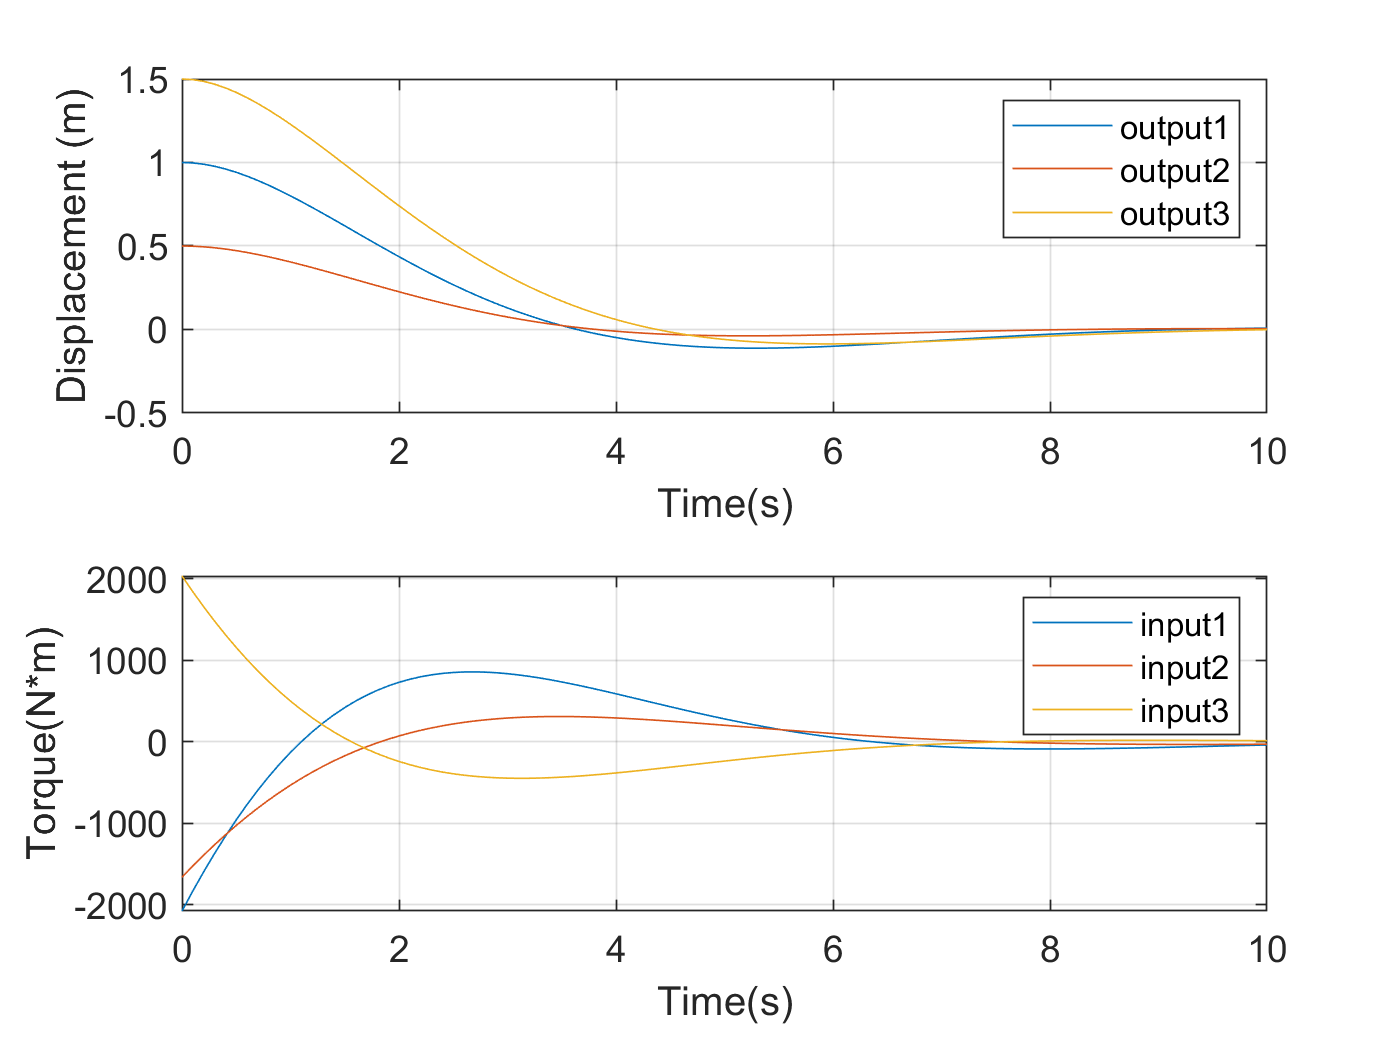

subplot(2,1,1)
plot(t_cl,y_cl)
legend('output1','output2','output3')
grid on 
xlabel('Time(s)')
ylabel('Displacement (m)')
set(gca,'fontsize',11) % change font size
subplot(2,1,2)
plot(t_cl,u)
legend('input1','input2','input3')
grid on 
hold off
xlabel('Time(s)')
ylabel('Torque(N*m)')
set(gca,'fontsize',11) % change font size

# Problem 3

Oberservability 

Obverbility = rank(obsv(ol_sys))

Obverbility = 6

The entire system is observable.

Controllability for each single **output**, and store the rank into an array.

for c = 1:3
    sub_sys = ol_sys(c,:);
    obsv_sub_sys(c) = rank(obsv(sub_sys));
end
obsv_sub_sys

obsv_sub_sys =      2     4     6


The with system with first or second output is **NOT** observable

obsv_sub_sys(4) = rank(obsv(ol_sys([1 2],:)))

obsv_sub_sys =      2     4     6     4


Sub-system with combination of output 1 and 2 is **NOT** observable.

obsv_sub_sys(5) = rank(obsv(ol_sys([2 3],:)))

obsv_sub_sys =      2     4     6     4     6


Sub-system with combination of output 2 and 3 is observable

obsv_sub_sys(6) = rank(obsv(ol_sys([1 3],:)))

obsv_sub_sys =      2     4     6     4     6     6


Sub-system with combination of output 1 and 3 is observable

# Problem 4

Define the oberser poles and place the poles,

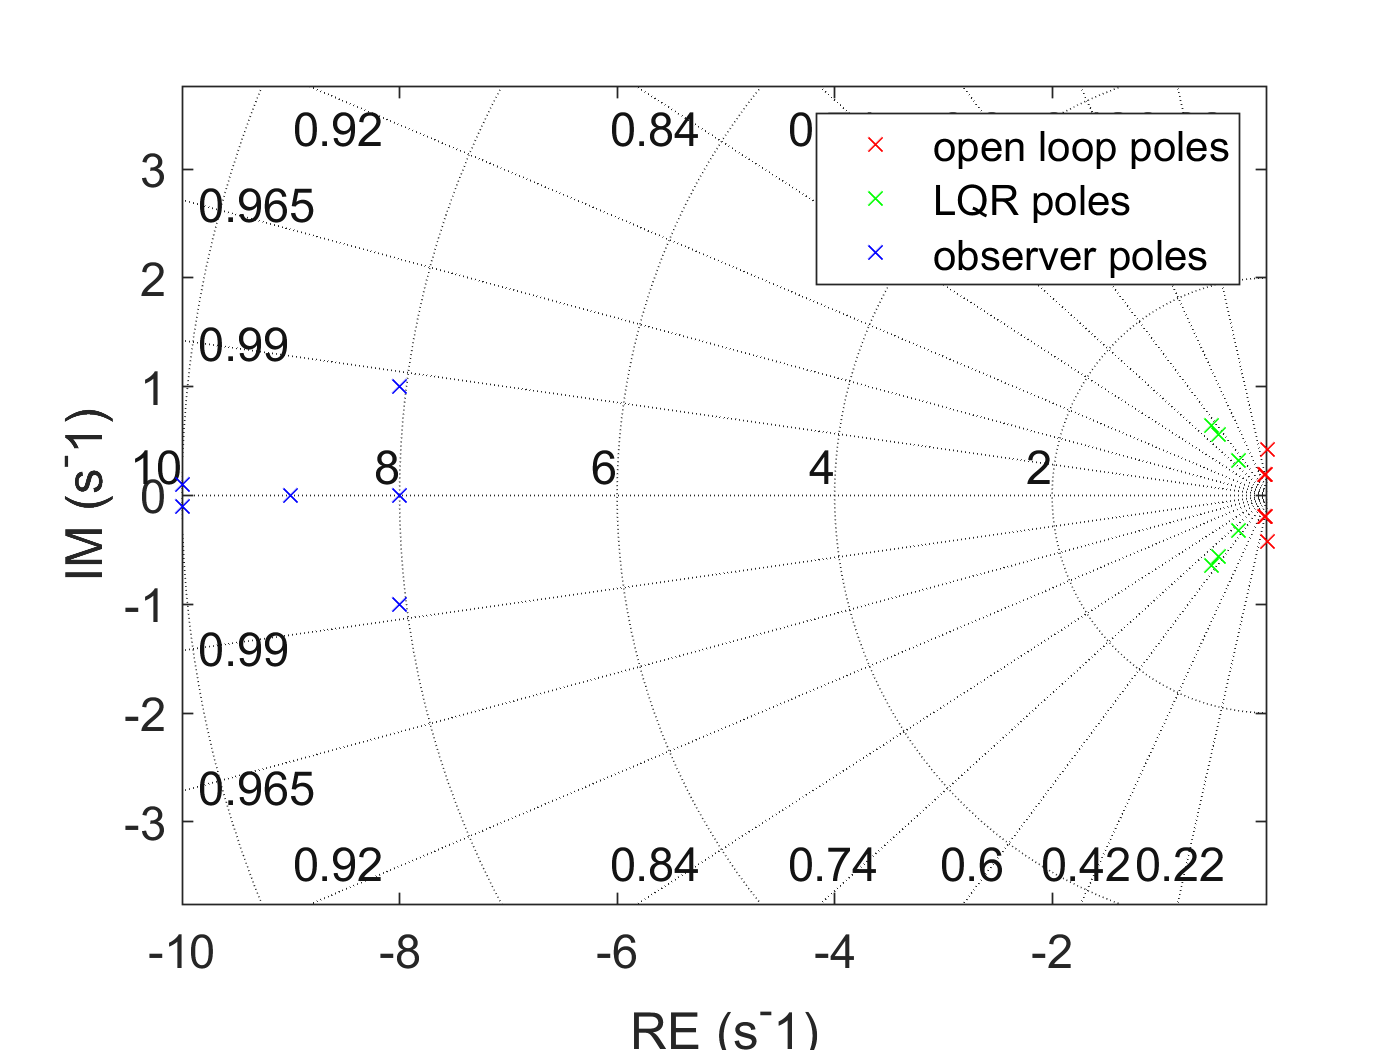

des_obs_poles = [-8 ... 
                 -9 ...
                 -10+0.1i ...
                 -10-0.1i ...
                 -8+1i ...
                 -8-1i];
K = place(A',C',des_obs_poles)';

figure
plot(pole(ol_sys),'x','color','r')
hold on 
plot(pole(cl_sys),'x','Color','g')
plot(des_obs_poles,'x','Color','b')
hold off  

xlabel('RE (s^-1)')
ylabel('IM (s^-1)')

set(gca,'fontsize',14) % change font size

axis equal
legend('open loop poles','LQR poles','observer poles','AutoUpdate','off')
sgrid

# Problem 5

Augmented state space system is


$$\begin{array}{l}
\left\lbrack \begin{array}{c}
\dot{x} \\
\dot{\hat{x} } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
A & -\mathrm{BG}\\
\mathrm{KC} & \hat{A} -K\hat{C} -\hat{B} G-K\left(D-\hat{D} \right)G
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\\
\hat{x} 
\end{array}\right\rbrack \\
\left\lbrack \begin{array}{c}
y\\
\hat{y} \\
u
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
C & -\mathrm{DG}\\
0 & \hat{C} -\hat{D} G\\
0 & -G
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\\
\hat{x} 
\end{array}\right\rbrack 
\end{array}$$


Output u for plotting

we also assume 


$$\begin{array}{l}
A=\hat{A} \text{ }\\
B=\hat{B} \\
C=\hat{C} \\
D=\hat{D} 
\end{array}$$


Construct LTI object with only state observer and no state feedback

Define a gain of zeros

G_Zeros = zeros(size(G));

A_aug1 = [A -B*G_Zeros; K*C (A-K*C-B*G_Zeros)];
C_aug1 = [C -D*G_Zeros;zeros(size(C)) C - D*G_Zeros; zeros(3,6) -G_Zeros];
obv_sys1 =ss(A_aug1,[],C_aug1,[]);

Augmented Initial condition

x0_aug1 = [x0;zeros(6,1)];
[y_obs1,t_obs1,x_obs1] = initial(obv_sys1,x0_aug1,1); %simulate for 1 second

Seperate output, estimated output and 

yo1 = y_obs1(:,1:3);
yo1_hat = y_obs1(:,4:6);
uo1 = y_obs1(:,7:9);

New IC for 2nd stage

x0_aug2 = x_obs1(end,:);

Construct LTI model with state observer and full state feedback

A_aug2 = [A -B*G; K*C (A-K*C-B*G)];
C_aug2 = [C -D*G;zeros(size(C)) C - D*G;zeros(3,6) -G];
obv_sys2 =ss(A_aug2,[],C_aug2,[]);

simulate for 9 second

[y_obs2,t_obs2,x_obs2] = initial(obv_sys2,x0_aug2,9); %simulate for 9 seconds

Seperate output, estimated output and 

yo2 = y_obs2(:,1:3);
yo2_hat = y_obs2(:,4:6);
uo2 = y_obs2(:,7:9);


Combine output, estimated output, input and time

yo = [yo1;yo2];
yo_hat = [yo1_hat;yo2_hat];
uo = [uo1;uo2];
to = [t_obs1;t_obs2+1];

plot

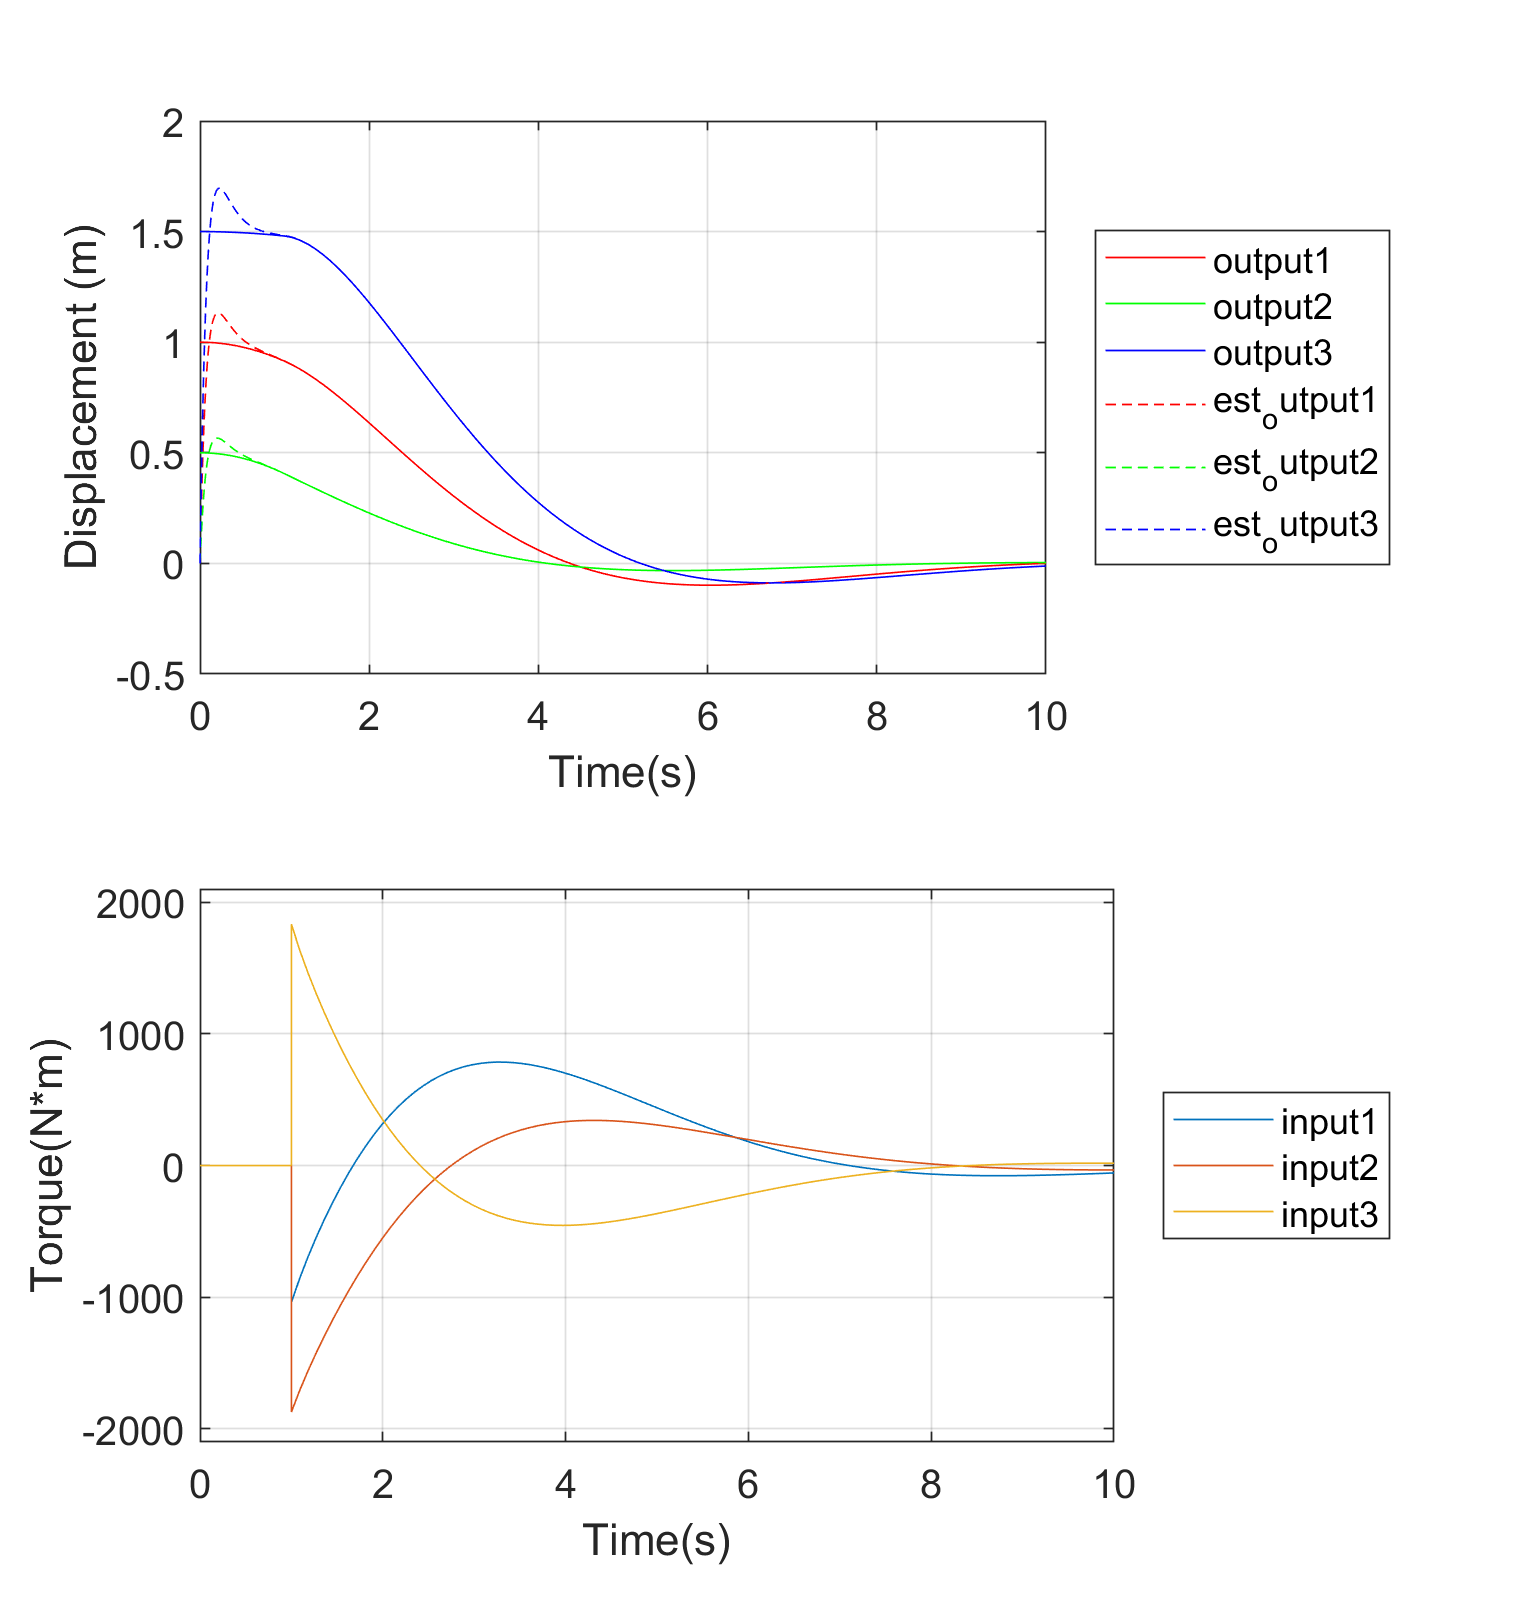

NameArray = {'Color'};
ValueArray = {'red','green','blue'}';

subplot(2,1,1);
p1 = plot(to,yo);
set(p1,NameArray,ValueArray)
hold on
p2 = plot(to,yo_hat,'--');
set(p2,NameArray,ValueArray)
hold off
legend('output1','output2','output3','est_output1','est_output2','est_output3','Location','eastoutside')
xlabel('Time(s)')
ylabel('Displacement (m)')
set(gca,'fontsize',12) % change font size
grid on

subplot(2,1,2)
plot(to,uo)
ylim([-2100 2100])
legend('input1','input2','input3','Location','eastoutside')
xlabel('Time(s)')
ylabel('Torque(N*m)')
grid on
set(gca,'fontsize',12) % change font size
set(gcf,'Units','Normalized','OuterPosition',[0 0 0.4 0.75])

Compute settling time

S_obs = lsiminfo(yo,to,'SettlingTimeThreshold',0.05); 

Compute maximum sellting time. 

for c = 1:3
    SettlingTimeArray_obs(c) = S_obs(c).SettlingTime;
end

%find max settling time
% maxSettlingTime_obs = max(SettlingTimeArray_obs);
disp(['maxSettlingTime = ', num2str(SettlingTimeArray_obs),' s'])

maxSettlingTime = 7.9588      6.9109      6.8998 s


Compute maximum input

umax_obs = max(abs(uo(:)));
disp(['umax_obs =', num2str(umax_obs),' N*m'])

umax_obs =1872.2938 N*m


# Problem 6

Buiilt the augmented Q and R for LQI

Qi = [Q zeros(6,3); zeros(3,6), diag([1 1 1])];
% Ri = 2E-7*diag([1 1 1.3]); %Ri is M by M 
Ri = 2E-7*diag([0.9 1.2 1.3]);

Angumented gain includes the first 6 state feedback gains and 3 integral gains

Ga = lqi(ol_sys,Qi,Ri); 

Separate state feedback gains and integral gains

G0 = Ga(:,1:6);
Gi = Ga(:,7:9);

# Problem 7

REF_sys = tf(eye(3)); % Static gain identity matrix 
SUM_sys1 = tf(eye(3)); % Static gain identity matrix 
SUM_sys2 = tf(eye(3)); % Static gain identity matrix 
G0_sys = tf(-G0); % Static gain G0 matrix (negated) 
GI_sys = tf(-Gi); % Static gain GI matrix (negated) 

Converting the 3x3 identity matrix into a cell array to serve as the matrix of numerator coefficients.

[1 0]  represents the polynomial 1*s+0 for all denominators: 

INTE_sys = tf(num2cell(eye(3)),[1 0]); 

Define the observer system to have the input and output we need


$$\begin{array}{l}
\left\lbrack \begin{array}{c}
\dot{\hat{x} } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
A-\textrm{KC}
\end{array}\right\rbrack \hat{x} +\left\lbrack \begin{array}{cc}
B & K
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
u\\
y
\end{array}\right\rbrack \\
\left\lbrack \begin{array}{c}
\hat{x} \\
\hat{y} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
1\\
C
\end{array}\right\rbrack \hat{x} +\left\lbrack \begin{array}{c}
0\\
D
\end{array}\right\rbrack u
\end{array}$$


A_aug3 = [A - K*C];
B_aug3 = [B K];
C_aug3 = [eye(6);C];

OBS_sys =ss(A_aug3,B_aug3,C_aug3,[]);

set(OBS_sys,'StateName',{'x1_hat','x2_hat','x3_hat','x4_hat','x5_hat','x6_hat'});
set(OBS_sys,'InputName',{'u1','u2','u3','y1','y2','y3'});
set(OBS_sys,'OutputName',{'x1_hat','x2_hat','x3_hat','x4_hat','x5_hat','x6_hat',...
    'y1_hat','y2_hat','y3_hat'});

use `append` to join dynamic system models of the elements of your block diagram

blksys = append(ol_sys,OBS_sys,REF_sys,...
                SUM_sys1,INTE_sys,G0_sys,GI_sys,SUM_sys2);
connections = [1 28 0; %OL_sys
               2 29 0;
               3 30 0;
               ...
               4 28 0; %OBS_sys
               5 29 0;
               6 30 0;
               7 1 0;
               8 2 0;
               9 3 0;
               ...
               13 13 -1; %SUM1_sys
               14 14 -2;
               15 15 -3;
               ...
               16 16 0; %INTE_sys
               17 17 0;
               18 18 0;
               ...
               19 4 0; %G0_sys
               20 5 0;
               21 6 0;
               22 7 0;
               23 8 0;
               24 9 0;
               ...
               25 19 0; %GI_sys
               26 20 0;
               27 21 0;
               ...
               28 22 25; %SUM2_sys
               29 23 26;
               30 24 27];
           

Input is  the input of REF_sys

inputs = [10 11 12];

output is the real output, estimated output and the input(for the ease of plotting)

outputs = [1 2 3 10 11 12 28 29 30]; %[y y_est u]
Connected_Sys = connect(blksys,connections,inputs,outputs);

# Problem 8

Construct augmented initial condition

0s for initial observer states and initial integrator states

x0_aug3 = [x0;zeros(9,1)];

Construct a time vector

Tfinal = 20; %final sim time (s)
Ts = 0.1; %data sample period (s)
Time = Ts * [0:round(Tfinal/Ts)]; %time vector (s)

Define referene input 

SA_ref = 0.5;
dAB_ref = 0;
dBC_ref = 1;

Reference matrix has 3 columns and one row for each time

for c = 1:length(Time)
reference(c,:) = [SA_ref dAB_ref dBC_ref];
end

Simulate

[y8,t8,x8] = lsim(Connected_Sys,reference,Time,x0_aug3);

extract the real output, estimated output and the input

y8_real = y8(:,1:3);
y8_est = y8(:,4:6);
u8 = y8(:,7:9);

plot

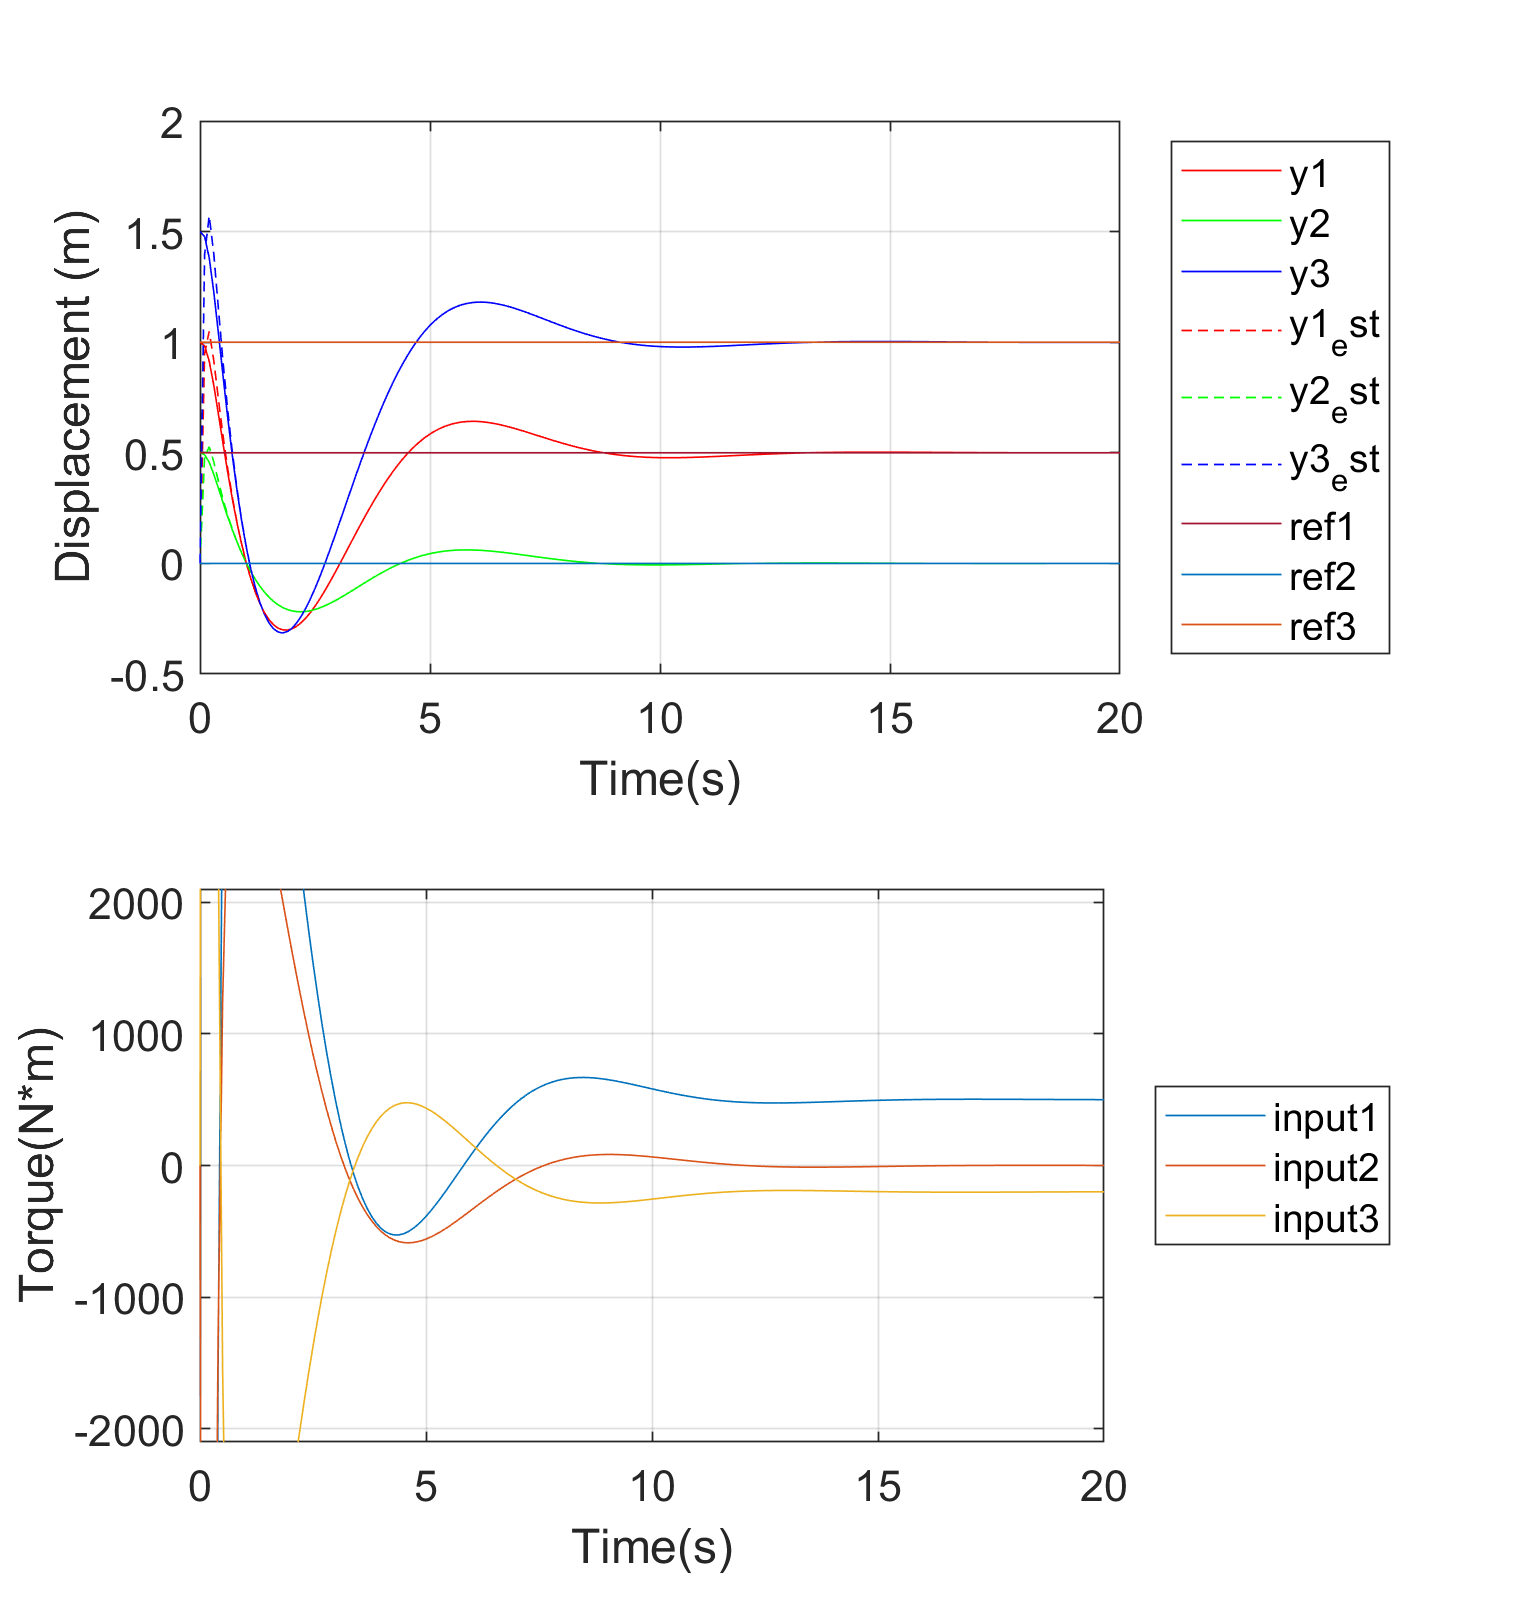

figure
subplot(2,1,1)
p7 = plot(t8,y8_real);
set(p7,NameArray,ValueArray)
hold on
p8 = plot(t8,y8_est,'--');
set(p8,NameArray,ValueArray)
p9 = plot(t8,reference);
xlabel('Time(s)')
ylabel('Displacement (m)')
grid on
legend('y1','y2','y3','y1_est','y2_est','y3_est','ref1','ref2','ref3','Location','eastoutside')
hold off
set(gcf,'Units','Normalized','OuterPosition',[0 0 0.4 0.75])
set(gca,'fontsize',13) % change font size

subplot(2,1,2)
plot(t8,u8)
xlabel('Time(s)')
ylabel('Torque(N*m)')
grid on
set(gca,'fontsize',13) % change font size
ylim([-2100 2100])
legend('input1','input2','input3','Location','eastoutside')

Compute maximum sellting time. 

S8 = lsiminfo(y8_real,t8,'SettlingTimeThreshold',0.05);
for c = 1:3
    SettlingTimeArray8(c) = S8(c).SettlingTime;
end

%find max settling time
maxSettlingTime = max(SettlingTimeArray8) ;
disp(['maxSettlingTime8 = ', num2str(maxSettlingTime),' s'])

maxSettlingTime8 = 7.9806 s
